# INTRODUCTION TO MATLAB

## **What is MATLAB**

MATLAB is a numerical computing environment and a proprietary programming language developed by Mathworks. Matlab's enviroment intagrates tools for numerical analysis, matricial calculus, signal processing and data visualization. MATLAB's name comes from *matrix laboratory, *since matrices are the principal objects in MATLAB computations.

The basic MATLAB contains: 

- Arithmetic operations: addition, substraction, multiplication, division, etc.

- Basic functions: exponential, logarithm, etc.

- Trigonometric functions: sine, tangent, etc.

- Special functions: Bessel functions, Fourier transforms, etc.

- Matrix operations: determinant, inverse.

- File Management functions.

- Data visualization functions: plots, images, contour plots, etc.

MATLAB can be expanded through a number of software toolboxes dedicated to deal with specific problems. There are toolboxes for signal processing, system control, sytem identification, statistics, neural networks, fuzzy logic, etc. 

## **First Steps in MATLAB**

The easiest way to start with matlab is definying  matrix for instance. To do that, you just have to follow this recipe:

- Decide a name for your variable.

- Asign the variable to its value using the equal sign (' = ').

- Include the matrix elements within square brackets (' [ ] ').

- Separate the column elements with  commas (or spaces).

- Utilize semicolons to indicate the end of a row.

Examples:

% This code creates a 3 x 3 matrix:
A = [1 2 3; 4 5 6; 7 8 9]

A =      1     2     3
     4     5     6
     7     8     9



% If you put a semicolon after a MATLAB
% expression MATLAB executes it but it's
% not shown on the console.

B = [7 8 9; 4 5 6; 1 2 3];

% To show the result, just type the name
% of the variable:

B

B =      7     8     9
     4     5     6
     1     2     3


The elements of a matrix can be defined on the fly using mathematical expressions:

% This is a 1 x 3 matrix:
x = [(-1.3)^2 sqrt(3) (1+2+3)*4/5]

x =     1.6900    1.7321    4.8000


Also, one can fill the elements of a matrix individually. In such a case, MATLAB redefines the dimensions of the matrix. 

For instance:

x(5) = abs(x(1))

x =     1.6900    1.7321    4.8000         0    1.6900


To generate vectors (1D matrices) you must follow the same rules that we used to generate matrices. Also, you can create vector with equispaced data elements using the MATLAB command ' : '. 

Try the following: 

x = 1: 5

x =      1     2     3     4     5


Additonally, you can include a step for the sequence of numbers:

i = 0: pi/4 : pi

i =          0    0.7854    1.5708    2.3562    3.1416


Negative steps are allowed too:

z = 6: -1: 1

z =      6     5     4     3     2     1


## Complex numbers in MATLAB

MATLAB also allows creating  variables / constants that are complex numbers, such as:

% You can represent the imaginary part of the complex using the symbol 'i'
z1 = 3 + 4i

z1 = 3.0000 + 4.0000i

% but also the symbol 'j'
z2 = 3 + 4j

z2 = 3.0000 + 4.0000i

Interestingly, many functions in MATLAB can be used for real and complex input arguments. Some of these functions are the following:

abs(x), acos(x), acosh(x), angle(x), asin(x), atan(x), atanh(x), ceil(x), conj(x), cos(x), cosh(x), exp(x), fix(x), floor(x), imag(x), log(x), log10(x), real(x), rem(x,y), round(x), sign(x), sin(x), sqrt(x), tan(x), and  tanh(x).

## Helpers and special functions

It is very useful to know which variables have been defined during the execution of the code, what are their current values, dimension, etc. To do that, you have to type the command:

whos

  Name      Size            Bytes  Class      Attributes

  A         3x3                72  double               
  B         3x3                72  double               
  C1        2x2                32  double               
  C2        2x2                32  double               
  C3        2x2                32  double               
  C4        2x2                32  double               
  C5        2x2                32  double               
  C6        2x2                32  double               
  D1        2x2                 4  logical              
  D2        2x2                 4  logical              
  D3        2x2                 4  logical              
  D4        2x2                 4  logical              
  D5        2x2                 4  logical              
  ans       1x1                 8  double               
  f         1x16              128  double               
  i         1x5                40  double               
  j         1x1               

As you can see, after using this command it appears on the screen a list of data relative to the set of MATLAB variables that have been stored in memory.

Other useful commands associated to data managing are:

-  who:

who


Your variables are:

A    C1   C3   C5   D1   D3   D5   f    j    n    z    z2   
B    C2   C4   C6   D2   D4   ans  i    m    x    z1   



-  what:

what


MATLAB Live Code in the current folder C:\Users\Biosignal\Desktop

Introduction_to_Matlab  




- which:

which('Introduction_to_Matlab.mlx')

C:\Users\Biosignal\Desktop\Introduction_to_Matlab.mlx


Additionaly, basic MATLAB includes the command 'help' that provides relevant information about its own core functions or functions from any installed toolbox. For instantes, just type:

help inv

 inv    Matrix inverse.
    inv(X) is the inverse of the square matrix X.
    A warning message is printed if X is badly scaled or
    nearly singular.
 
    See also slash, pinv, cond, condest, lsqnonneg, lscov.

    Reference page for inv



Futhermore, there are two other special functions in base matlab for variable management / visualization:

- clear

% clear removes every variable stored in the work space
clear
whos

- clc

% clc cleans the console
clc

## Special Variables

There exist in MATLAB a pair of reserved variable types: 'inf' and Nan'

- 'Inf' stands for infininte, and it is the result of division by 0:

5 / 0

ans = Inf

- 'Nan' means 'not a number', and it appears when the outcome of an operation is not well defined. For example:

0 / 0

ans = NaN

## Arithmetic Operations with Matrices

MATLAB usually works with matrices,so several arithmetic operations are implemented for them: 

- Addition:            '+'

- Substraction:     '-'

- Product:             '*'

- Left Inverse:       '\'

- Right Inverse:     '/'

- Power:               '^'

Examples:

% Definying the First Matrix:
A = [1 2; 3 4]

A =      1     2
     3     4


% Definying the Second Matrix
B = [4 3; 2 1]

B =      4     3
     2     1


% Addition:
C1 = A + B

C1 =      5     5
     5     5


% Substraction
C2 = A - B

C2 =     -3    -1
     1     3


% Product
C3 = A * B

C3 =      8     5
    20    13


% Left Inverse:
C4 = A \ B

C4 =    -6.0000   -5.0000
    5.0000    4.0000


% Right Inverse:
C5 = A / B

C5 =     1.5000   -2.5000
    2.5000   -3.5000


% Power
C6 = A ^ 2 % equivlent to A * A

C6 =      7    10
    15    22


## Relational Operations

We can perform relational operations in MATLAB perfoming element-wise comparations between two matrices (A and B), where the outcome is a new matrix with equal dimensions of as A and B, and whose elements are zeros or ones depending on if the condition proposed by the test are met or not, respectively. These relational operators are the following:

- Lower than:                 '<'

- Bigger than:                '>'

- Lower or equal to:       '<='

- Bigger or equal to       '>='

- Equal to:                     '=='

- Different from:             '~='

Examples:

% Definying the First Matrix:
A = [1 2; 3 4]

A =      1     2
     3     4


% Definying the Second Matrix
B = [4 3; 2 1]

B =      4     3
     2     1


% Lower than:
D1 = A < B

D1 = 2×2 logical array
   1   1
   0   0


% Bigger than:
D2 = A > B

D2 = 2×2 logical array
   0   0
   1   1


% Lower or equal to:
D3 = A <= B

D3 = 2×2 logical array
   1   1
   0   0


% Bigger or equal to:
D4 = A >= B

D4 = 2×2 logical array
   0   0
   1   1


% Different from:
D5 = A ~= B

D5 = 2×2 logical array
   1   1
   1   1


## Flow Control

MATLAB core include the commands 'for' , 'if'  and while for flow control.

### For loop:

'For' allows repeating groups of commands a number of times. For example, the following code creates a 3 x 3 matrix whose elements contain the value 1 / (i + j - 1).

n = 3

n = 3

m = 3

m = 3

A = zeros(n, m)

A =      0     0     0
     0     0     0
     0     0     0


for i = 1:m
    for j = 1:m
        A(i, j) = 1 / (1 + i -1)
    end
end

A =      1     0     0
     0     0     0
     0     0     0


A =      1     1     0
     0     0     0
     0     0     0


A =      1     1     1
     0     0     0
     0     0     0


A =     1.0000    1.0000    1.0000
    0.5000         0         0
         0         0         0


A =     1.0000    1.0000    1.0000
    0.5000    0.5000         0
         0         0         0


A =     1.0000    1.0000    1.0000
    0.5000    0.5000    0.5000
         0         0         0


A =     1.0000    1.0000    1.0000
    0.5000    0.5000    0.5000
    0.3333         0         0


A =     1.0000    1.0000    1.0000
    0.5000    0.5000    0.5000
    0.3333    0.3333         0


A =     1.0000    1.0000    1.0000
    0.5000    0.5000    0.5000
    0.3333    0.3333    0.3333


### While loop:

Alternatively, it can happen that a group of commands must be repeated until a condition is fulfilled. In such a case, the proper loop type to be used is a 'while' loop. As a example, let's compute the Fibonacci series while the addition of two consecutive terms has a value below 1000:

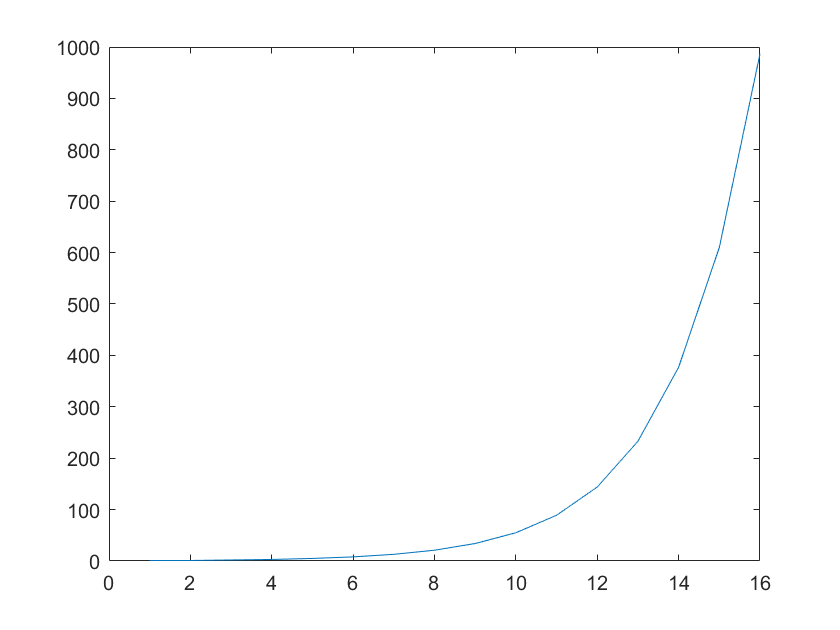

f = [1 1]; i = 1;
while f(i) + f(i+1) < 1000
    f(i+2) = f(i) + f(i+1);
    i = i + 1;
end
plot(f)

### If statement:

The if statement poses a condition, that is: If A is fulfilled, then perform some action. Othewhise, perform another one.

Example:

a = 2;
b = 3;

% If statement
if a>b
    m=a;
else
    m=b;
end

%Show the result:
disp(m);

     3



## Functions in MATLAB

Sometimes, we must create our own functions to solve a specific problem. To define a function you just have to follow this receipt:

*function [output variables] = function_name (input variables)*

Then, you have to include the body of the function (the function code).

Finally, save the function (you have to save .m file with the same name as the *function_name*).

Example: We are interested in computing the mean of a vector x. We will use the function my_mean, defined at the end of this document.

x = 1:10

x =      1     2     3     4     5     6     7     8     9    10


n = my_mean(x)

n = 5.5000

## Final Thoughts

In this first MATLAB document, you have learn the first steps needed to master this programming language. That is: Matrix operations, which include both arithmetical and relational operations, flow control statements and function definition. In the following lesson, you will learn how to plot your results using the data visualization tools present in MATLAB.

## Function my_mean

function n = my_mean(x)
% computes the mean of a vector x
    l = length(x);
    n = sum(x) / l;
    % end of the function body
end